% General Framework for Detection of where Artifacts affect the PPG signal 
% Week 2, Implementation of Sliding overlap window with Machine learning
% model for detection

fs=512;  % Sample Rate
Avg=8;   % Sampling Average
fs_avg=fs/Avg;  %Averaged Sampling Rate 64 Hz


type='Maxem';
window=64*3/4;
Overlap_perc=90;
Butterworth=butterworth

Butterworth =          FilterStructure: 'Direct-Form II, Second-Order Sections'      
              Arithmetic: 'double'                                     
               sosMatrix: [1 0 -1 1 -1.6917043661597 0.711648515536758]
             ScaleValues: [0.144175742231621;1]                        
     OptimizeScaleValues: true                                         
        PersistentMemory: false                                        
                                                                       

cd 'C:\Users\Mohammad Afaq\OneDrive\Documents\LUMS-Shared\ShareAbleSprojFolder\sproj research\Work\PPG signal Processing\RemovingMotionArtifacts\FrameWork'

Ref_data=xlsread("PPG_512-8-3min30sec.xlsx");
if strcmp(type,'Maxem')
    Ref_data=(Ref_data(:,3)+Ref_data(:,4))/2;
elseif strcmp(type,'Empatica')
    Ref_data=Ref_data(15*fs_avg:length(Ref_data)-10*fs_avg);
end

[perf_ref_data, PPG_ref_data] = pre_process(Butterworth,Ref_data,fs_avg);
[X_train_rest]=obtain_features(PPG_ref_data,window,Overlap_perc,fs_avg);
X_train=X_train_rest;

CI_Kur= createbound(X_train(:,1))

CI_Kur =     2.4420    1.0547


CI_Kur_=CI_Kur.*ones(length(X_train(:,1)),2);

CI_skew= createbound(X_train(:,2))

CI_skew =     0.8544   -0.8026


CI_skew_=CI_skew.*ones(length(X_train(:,2)),2);


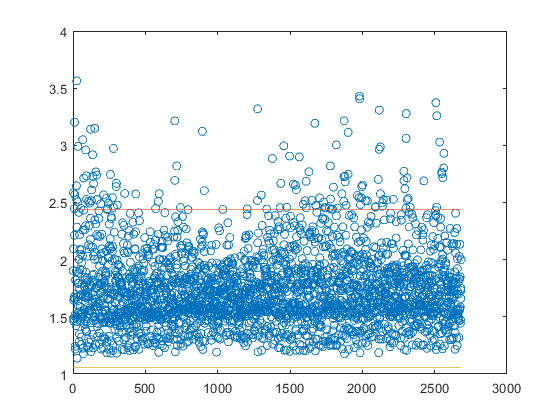

figure
plot(X_train(:,1),'o')
hold on
plot(CI_Kur_)

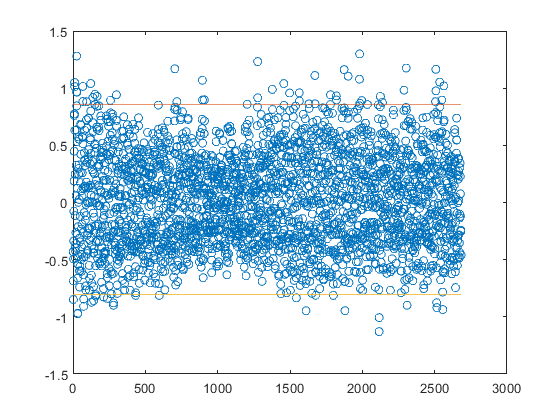


figure
plot(X_train(:,2),'o')
hold on
plot(CI_skew_)

%cd 'C:\Users\Mohammad Afaq\OneDrive\Documents\LUMS-Shared\ShareAbleSprojFolder\sproj research\Sheraz-SPROJ2\SPROJ2-Sheraz-Data Sets\Maxem_Raw'


Test_data=xlsread("testing.xlsx"); 
type='Maxem';


if strcmp(type,'Maxem')
    %Using Green LED signal
    PPG_data=(Test_data(:,3));
    PPG_data_ref_g2=(Test_data(:,4));
    [perf_data, PPG_data] = pre_process(Butterworth,PPG_data,fs_avg); %seperating perfusion and PPG waveform 
    [perf_data_g2, PPG_data_g2] = pre_process(Butterworth,PPG_data_ref_g2,fs_avg); %seperating perfusion and PPG waveform 
    ACC_x=(Test_data(:,7));
    ACC_y=(Test_data(:,8));
    ACC_z=(Test_data(:,9));
elseif strcmp(type,'Empatica')
    PPG_data=Test_data(15*fs_avg:length(Test_data)-1*fs_avg);
    [perf_data, PPG_data] = pre_process(Butterworth,PPG_data,fs_avg);
end


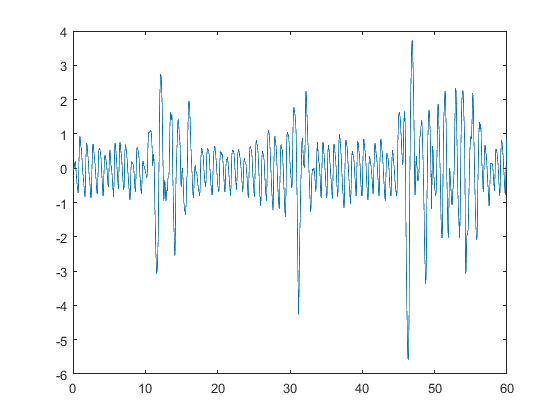


time=1:1:length(PPG_data);
time=time/fs_avg;

%PPG_data=bandpass(PPG_data,[1 4],64)
figure
plot(time,PPG_data(:,1))

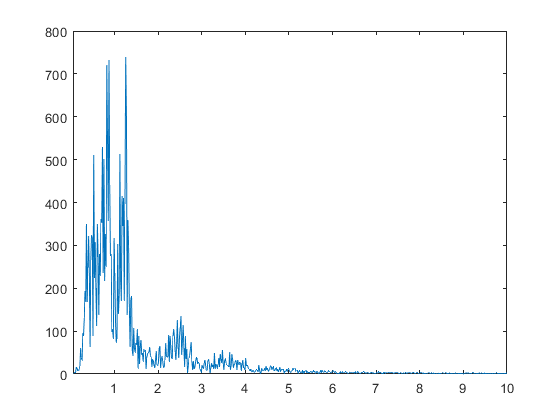

figure
freq_plot(PPG_data,fs_avg)


PPG_data=[PPG_data,transpose(time)]

PPG_data =    -0.0221    0.0156
   -0.0608    0.0313
   -0.0630    0.0469
   -0.0420    0.0625
   -0.0268    0.0781
   -0.0321    0.0938
   -0.0350    0.1094
   -0.0093    0.1250
    0.0101    0.1406
    0.0240    0.1563


PPG_data_g2=[PPG_data_g2,transpose(time)]

PPG_data_g2 =    -0.0396    0.0156
   -0.1103    0.0313
   -0.1217    0.0469
   -0.1083    0.0625
   -0.1089    0.0781
   -0.1254    0.0938
   -0.1342    0.1094
   -0.1087    0.1250
   -0.0923    0.1406
   -0.0775    0.1563



[X_test]=obtain_features(PPG_data,window,Overlap_perc,fs_avg)

X_test =     1.7316   -0.4635    0.7656
    1.6885   -0.3369    0.8438
    2.5483    0.4003    0.9219
    2.1046    0.4795    1.0000
    1.6378    0.3122    1.0781
    1.3738    0.1066    1.1563
    1.3551   -0.1468    1.2344
    1.5817   -0.3434    1.3125
    1.8800   -0.4336    1.3906
    1.8641   -0.3191    1.4688


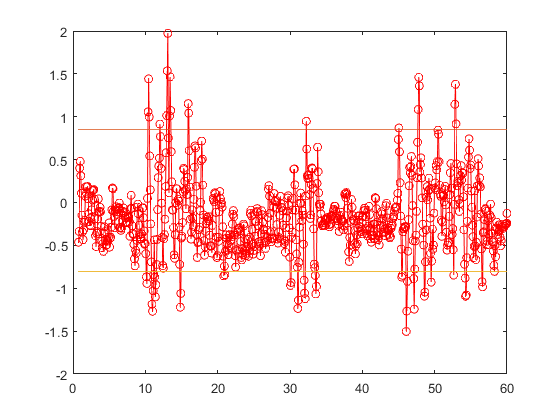

CI_skew_=CI_skew.*ones(length(X_test(:,3)),2);
figure
plot(X_test(:,3),X_test(:,2),'r-o')
hold on
plot(X_test(:,3),CI_skew_)

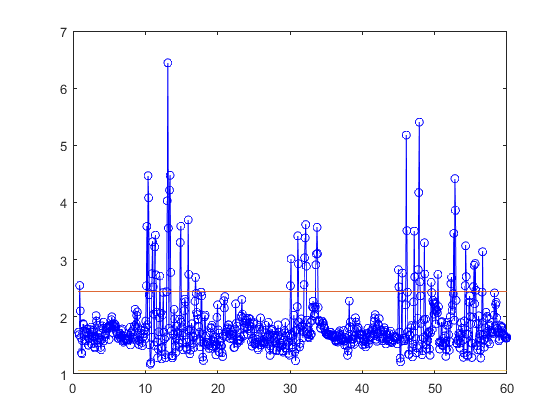


CI_kur_=CI_Kur.*ones(length(X_test(:,3)),2);
figure
plot(X_test(:,3),X_test(:,1),'b-o')
hold on
plot(X_test(:,3),CI_kur_)


jump=2;
windows=get_windows(X_test,jump,CI_Kur,CI_skew)

windows =     10    18
    30    34
    45    57


    10

   -0.0221
   -0.0608
   -0.0630
   -0.0420
   -0.0268
   -0.0321
   -0.0350
   -0.0093
    0.0101
    0.0240
    0.0323
    0.0542
    0.0908
    0.1267
    0.1565
    0.1609
    0.1641
    0.1826
    0.1933
    0.1813
    0.1662
    0.1442
    0.1044
    0.0739
    0.0443
   -0.0025
   -0.0696
   -0.1336
   -0.1807
   -0.2254
   -0.2619
   -0.2910
   -0.3284
   -0.3801
   -0.4283
   -0.4665
   -0.4977
   -0.5274
   -0.5561
   -0.5716
   -0.5929
   -0.6346
   -0.6691
   -0.7018
   -0.7269
   -0.7258
   -0.6897
   -0.6132
   -0.4982
   -0.3510
   -0.1810
    0.0011
    0.1707
    0.3335
    0.5053
    0.6463
    0.7441
    0.8214
    0.8860
    0.9276
    0.9224
    0.9053
    0.8891
    0.8655
    0.8252
    0.7695
    0.7195
    0.6760
    0.6437
    0.6285
    0.6306
    0.6190
    0.6036
    0.5709
    0.5168
    0.4774
    0.4239
    0.3643
    0.3072
    0.2502
    0.1889
    0.1150
    0.0359
   -0.0319
   -0.0721
   -0.0966
   -0.1208
   -0.1570
   -0.2072
   -0.2538
  

i = 1

grad = 'negative'

shift = -0.4389

replace =     0.5915
    0.5625
    0.5242
    0.4773
    0.4270
    0.3736
    0.3202
    0.2646
    0.2047
    0.1495


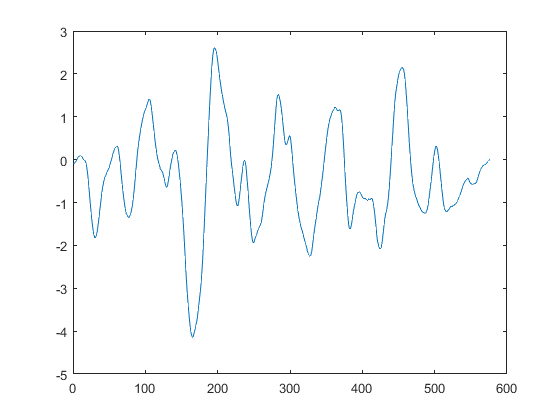

i = 2

temp =     30    34


grad = 'negative'

shift = -0.8736

replace =     0.8528
    0.7718
    0.6894
    0.6031
    0.5217
    0.4519
    0.3917
    0.3291
    0.2662
    0.2115


with =     0.1918
    0.1288
    0.0612
    0.0043
   -0.0500
   -0.1070
   -0.1618
   -0.2045
   -0.2391
   -0.2835


replace =     0.1918
    0.1108
    0.0284
   -0.0579
   -0.1393
   -0.2092
   -0.2693
   -0.3319
   -0.3949
   -0.4495


PPG_data =    -0.0221    0.0156
   -0.0608    0.0313
   -0.0630    0.0469
   -0.0420    0.0625
   -0.0268    0.0781
   -0.0321    0.0938
   -0.0350    0.1094
   -0.0093    0.1250
    0.0101    0.1406
    0.0240    0.1563


i = 3

grad = 'positive'

shift = 0.8269

replace =    -0.6145
   -0.5228
   -0.4517
   -0.4066
   -0.3923
   -0.3894
   -0.3984
   -0.4280
   -0.4558
   -0.4744


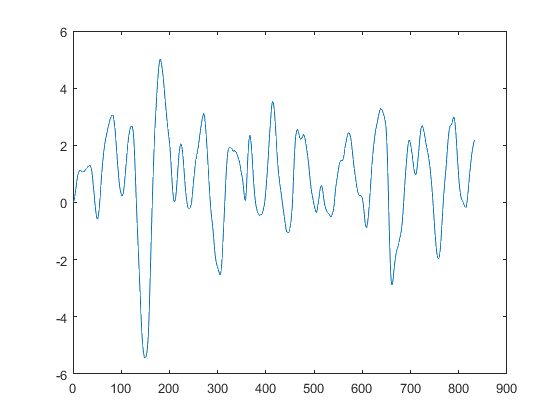

[temp,ref_visual,replaced_visual_1,replaced_visual_2]=visualize(windows,PPG_data,PPG_data_g2,ACC_x,ACC_y,ACC_z);

figure
subplot(2,1,1)
plot(PPG_data(:,1))
subplot(2,1,2)
[perf,temp]=pre_process(Butterworth,temp(:,1),fs_avg)

perf =     0.0380
    0.0368
    0.0357
    0.0347
    0.0336
    0.0325
    0.0315
    0.0304
    0.0294
    0.0284


temp =     0.0150
    0.0525
    0.0886
    0.1069
    0.1073
    0.1022
    0.0982
    0.0866
    0.0640
    0.0370


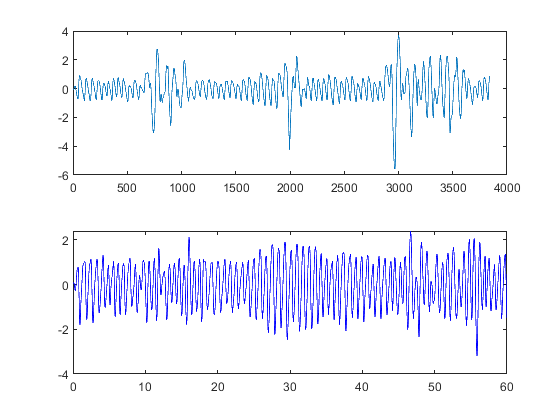

plot(time,temp(:,1),'b')
hold on

%plot(time,ref_visual,'r')
%hold on
%plot(time,replaced_visual_1,'k')
%hold on
%plot(time,replaced_visual_2,'g')




function [PPG_data,ref_visual, replaced_visual_1,replaced_visual_2]=visualize(windows,PPG_data,Ref_PPG_g2,ACC_x,ACC_y,ACC_z)
    dim=size(windows);
    total_windows=dim(1);
    display(windows(1,1))
    ref_visual=zeros(length(PPG_data(:,1)),1)*mean(PPG_data(:,1));
    replaced_visual_1=zeros(length(PPG_data(:,1)),1)*mean(PPG_data(:,1));
    replaced_visual_2=zeros(length(PPG_data(:,1)),1)*mean(PPG_data(:,1));
    display(PPG_data(:,1));
    for i=1:total_windows
        display(i)
        init=windows(i,1);
        fin=windows(i,2);
        
        if fin*64 < length(PPG_data)
            if fin-init<6
                %if fin-init>10
                 %   if init>10
                 %       init=init-5
                 %   end
                 %   if fin +2 < length(PPG_data)/64
                 %       fin=fin+2
                  %  end
               % end
                
                if init>6
                    temp=[init fin]
                    replace=Averaging_window(PPG_data(:,1),temp);
                    with=PPG_data(init*64:fin*64,1)
                    
                    difference=replace(1)-with(1);
                    
                    replace=replace-difference
                    PPG_data(init*64:fin*64,1)=replace
                    replaced_visual_1(init*64:fin*64,1)=PPG_data(init*64:fin*64,1);
                end
                
                
            else
                if init>6
                    init=init-1;
                    temp=[init fin];
                    g_data=PPG_data(init*64:fin*64,1);
                    %ref_g_data=Ref_PPG_g2(init*64:fin*64,1);
                    ref_g_data=Averaging_window(PPG_data(:,1),temp);
                    
                    figure 
                    plot(g_data-ref_g_data)
                    a_x=ACC_x(init*64:fin*64,1);
        
                    %[g_data,ref_g_data] = SGolay_Filter(g_data,ref_g_data,3,55);
                    [g_data] = AdaptiveFilter(ref_g_data,g_data,1,0.01,16,0.99,1);
                    
                    [HRF] = HeartRate(PPG_data((init-5)*64:init*64));
                    %[g_data] = NotchFilter(g_data,HRF,64);
                   % else
                        %g_data = g_data;
                    %end
                    PPG_data(init*64:fin*64,1)=sgolayfilt(g_data,3,33);
                    replaced_visual_2(init*64:fin*64,1)=PPG_data(init*64:fin*64,1);
                    
                end
                
            end
            ref_visual(init*64:fin*64,1)=PPG_data(init*64:fin*64,1);
        end

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        %Code To filter the window here
        %window_data=sgolayfilt(window_data,4,32 +1)
        
        %d=window_data;
        %x=window_data-ref_data;
        %mu=0.05;
        %lms=dsp.LMSFilter(10000,'Method','Normalized LMS','StepSize',mu)
        %[y,error] = lms(x,d);
        
      
        
        %PPG_data(init*64:fin*64,1)=bandpass(PPG_data(init*64:fin*64,1),[1 1.5],64);
    
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        %time=init*64:1:fin*64;
       % time=time/64;
        %figure
        %subplot(2,1,1)
        %plot(time,window_data)
       % subplot(2,1,2)
        %freq_plot(window_data,64)

    end
end

function [PPG_Data] = AdaptiveFilter(PPG_sig,Ref_sig,ref_type,mu,len,forf,inic)
    d1 = PPG_sig;
    d2 = Ref_sig;
    if ref_type == 1
        ref = d1-d2;
        ref=sgolayfilt(ref,1,65);
        
        mu = mu;
        rls1 = dsp.RLSFilter(len,'Method','Sliding-window RLS','ForgettingFactor',forf,'InitialInverseCovariance',inic);
        [x1,~] = rls1(d1,ref);
        [x2,~] = rls1(d2,ref);
    
        [Ta] = fundamental_period_extraction(x1);
        [new_ref_sig1,new_ref_sig2] = B_optim(x1,x2,ref,Ta,mu);
        %lms = dsp.LMSFilter(32,'Method','Normalized LMS','StepSize',mu);
        rls2 = dsp.RLSFilter(len,'Method','Sliding-window RLS','ForgettingFactor',forf,'InitialInverseCovariance',inic);
        [ppg_red,~] = rls2(new_ref_sig2,x1);
        %[ppg_IR,~] = rls2(new_ref_sig2,x2);
    else
        ref = d2;

        rls1 = dsp.RLSFilter(32,'Method','Sliding-window RLS','ForgettingFactor',0.999,'InitialInverseCovariance',0.1);
        [x1,~] = rls1(d1,ref);
        [x2,~] = rls1(d2,ref);
        rls2 = dsp.RLSFilter(32,'Method','Sliding-window RLS','ForgettingFactor',0.999,'InitialInverseCovariance',0.1);
        [ppg_red,~] = rls2(d1-x1,x1);
    end


    PPG_Data = d1 - ppg_red; %(ppg_IR/max(ppg_IR));
end


function [new_ref_sig1,new_ref_sig2] = B_optim(x1,x2,ref_sig,Ta,mu)
    %B_OPTIM Summary of this function goes here
    %   Detailed explanation goes here
    %lms = dsp.LMSFilter(640,'Method','mmse','StepSize',mu)
    %[ppg_red,error] = lms(new_ref_sig2,x1);
    
    rv = mean(x2./ref_sig);
    s_as = x1 - rv*x2;%dot(rv,transpose(x2));
    
    lms = dsp.LMSFilter('Length',64,'Method','LMS','StepSize',mu);
    [est_Sas] = lms(x1,s_as);
%    [mse,meanw,w,tracek] = msesim(lms,s_as,x1);
 %   est_Sas = filter([0 -w(2:end)],1,x2);
    est_Sas2 = x1 - est_Sas;
    filter_coeff = lpc(est_Sas2,Ta);
    
    a = (mean(x1.*x1,'all')-rv*mean(x1.*x2,'all'))/mean(s_as,'all');
    b = (a*rv)/(1-a);
%     if b > 20
%         b = 0.1;
%     end
    x3 =[];
    for i=1:length(x2)
        if x2(i)>x1(i)
            x3(i) = 0.95*x2(i);
        elseif x2(i)<x1(i)
            x3(i) = 1.05*x2(i);
        else
            x3(i) = x2(i);
        end
    end
        b = 1.05;
    %e1 = x1 - a.*s_as;
    
    
    new_ref_sig1 =  est_Sas2;
    new_ref_sig2 = x1 - x3'; 
    
end


function [Ta] = fundamental_period_extraction(x1)
    x = xcorr(x1);
    l = length(x);
    t_max = floor(l/3);
    t = 1:t_max;
    y = zeros(l,1);
    z = [];
    for i = 1:t_max
        y(i) = 1;
        y(2*i) = 0.9;
        y(3*i) = 0.8;
        z1 = y.*x;
        Z = fft(z1);
        pow = Z.*conj(Z);
        pow_acc = sum(Z);
        z = [z pow_acc];
    end
    [~,ind] = max(z);
    Ta = ind;
end



function [PPG_sig_proc] = NotchFilter(PPG_sig,HRF,fs)
    
%     notchspec = fdesign.notch('N,F0,BW',6,HRF,0.1,fs);
%     notchfilt = design(notchspec,'SystemObject',true);
%     %fvt= fvtool(notchfilt, 'Color','white');
%     notchspec1 = fdesign.notch('N,F0,BW',6,2*HRF,0.1,fs);
%     notchfilt1 = design(notchspec1,'SystemObject',true);
    w0 = HRF/(fs/2);
    bw = w0/45;
    [b,a] = iirnotch(w0,bw);
    
    w1 = (HRF*2)/(fs/2);
    bw1 = w1/90;
    [b1,a1] = iirnotch(w1,bw1);
    
    proc_sig = filter(b,a,PPG_sig);
    proc_sig1 = filter(b1,a1,PPG_sig);
    
    noise = PPG_sig - proc_sig - proc_sig1;
    PPG_sig_proc = PPG_sig - noise;
    PPG_sig_proc = normalize(PPG_sig_proc);
end

function [HRF] = HeartRate(PPG_sig)
    [~,loc] = findpeaks(PPG_sig,64,'MinPeakDistance',0.7);
    peak_diff = [];
    for i=1:length(loc)-1
        peak_diff(i) = loc(i+1) - loc(i); 
    end
    HRF = mean(peak_diff);
end


function [replace] = Averaging_window(PPG,windows)

    if (windows(1)-5)>0
        data=PPG((windows(1)-5)*64:(windows(1)-1)*64);
        %plot(data)
    else
        display("need more data to calibrate")
        return
    end
    
    double_der=diff(diff(data));

    [peaks,locs]=findpeaks(double_der,'MinPeakHeight',0.02,"MinPeakDistance",32);
    
    distances=[];
    
    for i=1:length(locs)-1
        distances=[distances abs(locs(i)-locs(i+1))];
    end
    
    len=min(distances);
    
    PPG_sum=[];
    for i=1:length(locs)-1
        PPG_sum=[PPG_sum data(locs(i):locs(i)+len)];
    end
    
    sum=zeros(len+1,1);
    for i=1:length(distances)
        sum=sum+PPG_sum(:,i);
    end
    
    Averaged=sum/length(distances);
    plot(PPG_sum)
    plot(Averaged)
    
    
    window=windows(2)-windows(1);
    samples=window*64;
    d=length(Averaged);
    bias=Averaged(length(Averaged))-Averaged(1);
    
    
    second_sample=PPG(windows(1)*64+10);
    first_sample=PPG(windows(1)*64);
    last_sample=PPG((windows(1)*64)-10);
    %grad=''
    initial_index=0;
    
    if second_sample>first_sample 
        grad='positive'
        if first_sample>last_sample
            
            %display('positive')
            for i=2:length(Averaged)-1
                gradi=Averaged(i+1)-Averaged(i-1);
                if gradi>0
                    if Averaged(i)<second_sample && Averaged(i)>first_sample
                        initial_index=i;
                    end
                end
            end
        end
    end
    
    if second_sample<first_sample 
        grad='negative'
        if first_sample<last_sample
            
            %display('negative')
            for i=2:length(Averaged)-1
                gradi=Averaged(i+1)-Averaged(i-1);
                if gradi<0
                    if Averaged(i)>second_sample && Averaged(i)<first_sample
                        initial_index=i;
                    end
                end
            end
        end
    end
    
    if initial_index==0
        if grad=="positive"
            initial_index=round(length(Averaged)/2)
        elseif grad=="negative"
            initial_index=1
        end
    end
    %display(initial_index)
    replace=[Averaged(initial_index:length(Averaged))];
    used=length(Averaged)-initial_index;
    %plot(replace)
    
    choice=[];
    i=1;
    while(used<samples)
        if (samples-used)<d
            choice=Averaged(1:samples-used);
        else
            choice=Averaged;
        end
        choice=choice+i*bias;
        replace=[replace;choice];
        used=used+length(choice);
        i=i+1;
    end
    
    trend=sgolayfilt(replace,1,1*64+1);
    %plot(replace)
    %figure
    %plot(replace-trend)
    replace=replace-trend;
    
    shift=replace(1)-last_sample
    replace=replace-shift
    %plot(temp)
    %plot(PPG)
end

function [PPG,Ref] = SGolay_Filter(PPG_sig,Ref_sig,order,wind_len)
    PPG = sgolayfilt(PPG_sig,order,wind_len);
    Ref = sgolayfilt(Ref_sig,order,wind_len);
end

function khirki = get_windows(X_test,jump,CI_Kur,CI_skew)

    window=[];
    time_init=0;
    time_final=0;
    windows=[];
    i=1;
    
    while i < length(X_test(:,1))
        if ((X_test(i,1)>CI_Kur(1)) ||  (X_test(i,1)<CI_Kur(2))) && ((X_test(i,2)>CI_skew(1)) ||  (X_test(i,2)<CI_skew(2)))
            time_init=round(X_test(i,3)-0.5);
            if time_init==0
                time_init=1;
            end
            window=[];
            prev_time=time_init;
            time_final=0;
            index=i;
            
            while 1
                count_motion=0;
                if prev_time + jump > length(X_test(:,1))
                    break
                end
                while X_test(index,3) < prev_time + jump
                    if ((X_test(index,1)>CI_Kur(1)) ||  (X_test(index,1)<CI_Kur(2))) && ((X_test(index,2)>CI_skew(1)) ||  (X_test(index,2)<CI_skew(2)))
                        count_motion=count_motion+1; 
                    end
                    index=index+1;
                    if index > length(X_test(:,1))
                        index=length(X_test(:,1));
                        break
                    end
                end
                if count_motion<1
                    break
                else
                    
                end
                prev_time=round(X_test(index,3));              
            end
            time_init=time_init;
            time_final=prev_time;
            if index> length(X_test(:,1))
                window=[time_init length(X_test(:,1))];
                break
            else
                window=[time_init time_final];
            end
            windows=[windows;window];
            i=index;
        end
        i=i+1;
    end
    khirki=windows;
end

function freq_plot(data,fs)
    FM = (abs(fftshift(fft(data)))); 	
    FF = linspace(-fs/2,fs/2,length(FM)); 
    plot(FF,FM)
    xlim([0.05 10])
end


function [perf, PPG] = pre_process(fil,data,fs)
    perf=sgolayfilt(data,2,4*fs +1);
    PPG=data-perf;
    PPG=-1*PPG;
    PPG=filter(fil,PPG);
    PPG=normalize(PPG);
    
end

function CI= createbound(data)
    m=mean(data);
    s=std(data);
    CI=[m+2*s m-2*s];
    %CI=CI.*ones(length(X_train(:,1)),2)
end

function [feature_matrix,time]=obtain_features(data,window_size,Overlap,fs)
    Input_data=data;
    window=window_size;
    Overlap_perc=Overlap;
    
    current_pos=1;
    prev_pos=1;
    last_iter=0;
    
    Kur=[];
    Skew=[];
    Standard_dev=[];
    time=[];
    
    len_signal=length(Input_data);
    
    while 1
        if (prev_pos+window) < len_signal
            current_pos=prev_pos+window;
        else
            current_pos=len_signal;
            last_iter=1;
        end
        
        data_segment=Input_data(prev_pos:current_pos);
        Kur=[Kur kurtosis(data_segment)];
        Skew=[Skew skewness(data_segment)];
        Standard_dev=[Standard_dev std(data_segment)];
        
        if last_iter==0
            time=[time current_pos/fs];
        elseif last_iter==1
            time=[time len_signal/fs];
            break
        end
        
        prev_pos=current_pos- round((Overlap_perc/100) *window);
    end
    
    Kur=transpose(Kur);
    Skew=transpose(Skew);
    Standard_dev=transpose(Standard_dev);
    time=transpose(time);

    
    feature_matrix=[Kur,Skew,time];

end


function Hd = butterworth
    %BUTTERWORTH Returns a discrete-time filter object.
    
    % MATLAB Code
    % Generated by MATLAB(R) 9.9 and Signal Processing Toolbox 8.5.
    % Generated on: 02-Apr-2021 15:37:40
    
    % Butterworth Bandpass filter designed using FDESIGN.BANDPASS.
    
    % All frequency values are in Hz.
    Fs = 64;  % Sampling Frequency
    
    N   = 2;    % Order
    Fc1 = 0.6;  % First Cutoff Frequency
    Fc2 = 4;    % Second Cutoff Frequency
    
    % Construct an FDESIGN object and call its BUTTER method.
    h  = fdesign.bandpass('N,F3dB1,F3dB2', N, Fc1, Fc2, Fs);
    Hd = design(h, 'butter');
end

function Hd = stopbandfilter(freq)
    %STOPBANDFILTER Returns a discrete-time filter object.
    
    % MATLAB Code
    % Generated by MATLAB(R) 9.9 and Signal Processing Toolbox 8.5.
    % Generated on: 06-Apr-2021 11:59:52
    
    % FIR Window Bandstop filter designed using the FIR1 function.
    
    % All frequency values are in Hz.
    Fs = 64;  % Sampling Frequency
    
    N    = 100;      % Order
    Fc1  = freq-freq/4;      % First Cutoff Frequency
    Fc2  = freq+freq/4;        % Second Cutoff Frequency
    flag = 'scale';  % Sampling Flag
    Beta = 0.5;      % Window Parameter
    
    % Create the window vector for the design algorithm.
    win = kaiser(N+1, Beta);
    
    % Calculate the coefficients using the FIR1 function.
    b  = fir1(N, [Fc1 Fc2]/(Fs/2), 'stop', win, flag);
    Hd = dfilt.dffir(b);
end